# Laboratorio 5 — Repaso: sistemas lineales y no lineales

**Curso:** Laboratorio de computación científica (IELE 2009 L) — Sección 1 — 2026-20. **Profesora:** Valentina Reyes Martínez. **Asistente graduado:** Diego Santiago Jiménez Beltrán.

**Integrantes:** [Nombre integrante 1] — [Nombre integrante 2]

**Alcance de esta versión:** Primer punto (diagnóstico) y Segundo punto (ecuaciones no lineales). El archivo se ejecuta con **Run All**: la primera celda limpia el *Workspace* y agrega al *path* la carpeta `funciones` (métodos reutilizados), ubicada junto a este Live Script.

clear; close all; format short g
addpath(fullfile(fileparts(which('Lab5_Repaso')), 'funciones'));
fprintf('Versión de MATLAB: %s\n', version);

Versión de MATLAB: 26.1.0.3346908 (R2026a) Update 5


## Parámetros de personalización


$$c = 0.50 + 0.05\,d_7,\qquad p = 1 + 0.05\,d_7,\qquad q = 1 + 0.05\,d_8,\qquad s = 1 + 0.05\,d_9 .$$


**Importante:** reemplace `codigo` por el código real de un integrante y ejecute **Run All**. Las cifras citadas en el análisis se imprimen desde las variables, por lo que se actualizan solas. En los puntos 1 y 2 solo interviene $d_7$ (vía $c$); se verificó que para todo $d_7\in\{0,\dots,9\}$ ($c\in[0.50,\,0.95]$) el comportamiento cualitativo descrito en el texto es el mismo.

codigo = '202012345';                 % <-- REEMPLAZAR por el código de un integrante (9 dígitos)
d = codigo - '0';
assert(numel(d) == 9 && all(d >= 0 & d <= 9), 'El código debe tener exactamente 9 dígitos.');
c = 0.50 + 0.05*d(7);  p = 1 + 0.05*d(7);  q = 1 + 0.05*d(8);  s = 1 + 0.05*d(9);
parametros = table(string(codigo), d(7), d(8), d(9), c, p, q, s, ...
    'VariableNames', {'codigo','d7','d8','d9','c','p','q','s'})

parametros = 1×8 table
      codigo       d7    d8    d9     c       p       q      s  
    ___________    __    __    __    ____    ____    ___    ____

    "202012345"    3     4     5     0.65    1.15    1.2    1.25

	Get insights using Copilot


## Objetivos y criterios comunes

Clasificar cada problema e identificar la evidencia necesaria; comparar bisección, falsa posición, punto fijo, Newton y secante en garantía, velocidad local, sensibilidad y costo, contrastando cada predicción con valores concretos. Métricas:


$$E_a^{(n)} = |x_n - x_{n-1}|,\qquad E_r^{(n)} = \frac{|x_n - x_{n-1}|}{\max(|x_n|,\varepsilon)},\qquad r_n = |f(x_n)| .$$


**Criterio de parada.** Un método declara `convergio` solo si $E_a^{(n)} \le \mathrm{tol}_x$ **y** $r_n \le \mathrm{tol}_f$ simultáneamente: un paso pequeño no implica convergencia y un residuo pequeño no implica error pequeño. Otros estados: `intervalo_invalido` ($f(a)f(b)>0$), `derivada_pequena` ($|f'(x_n)|<10^{-12}$), `denominador_nulo` (secante), `divergio` ($|x_n|>10^{8}$ o no finito) y `max_iter`.

**Funciones reutilizadas.** Están en la carpeta `funciones`; el encabezado de cada archivo identifica las correcciones hechas a las versiones anteriores: test de signo con `sign()` (evita *underflow*/_overflow_ de $f(a)f(b)$), control de $f'$ y del denominador **antes** de dividir, criterio doble, detección de divergencia, conteo exacto de evaluaciones y una salida común (raíz, residuo, paso, iteraciones, evaluaciones, estado e historial).

tolx = 1e-8;  tolf = 1e-8;  maxit = 100;  tolDer = 1e-12;

## Primer punto. Diagnóstico: ¿qué problema tengo y qué evidencia necesito?

### 1.1 Clasificación (antes de ejecutar MATLAB)

**a.** $A\mathbf{x}=\mathbf{b}$, $A$ conocida y cuadrada: **lineal**. Falta $\mathbf{b}$, verificar que $A$ sea no singular y su condicionamiento ($\kappa(A)$, `rcond`), y su estructura (simetría, dominancia, dispersión) para elegir método directo o iterativo.

**b.** $x^3-4x+c=0$: **no lineal** (cúbica). $c$ lo fija la personalización; falta decidir **cuál** de las (hasta tres) raíces reales se busca y dar un intervalo con cambio de signo o una semilla. $f'(x)=3x^2-4$ es conocida (habilita Newton) pero se anula en $x=\pm2/\sqrt3$.

**c.** $V_s - V_D - RI_s(e^{V_D/(nV_T)}-1)=0$: **no lineal** en $V_D$ e **insuficientemente especificado**: faltan $V_s, R, I_s, n, V_T$ y el rango físico de $V_D$. Con ellos, $F'(V_D) = -1-\frac{RI_s}{nV_T}e^{V_D/(nV_T)}<0$: raíz única y bisección garantizada en $[0,V_s]$; hay riesgo de *overflow* de la exponencial con semillas grandes.

**d.** $A(\alpha)\mathbf{x}=\mathbf{b}$ con $h(\alpha)=0$: **insuficientemente especificado** y, en conjunto, **no lineal** en dos etapas. Faltan $h$, intervalo/semilla y cuál raíz es físicamente válida; luego la forma de $A(\cdot)$, $\mathbf{b}$ y verificar que $A(\alpha^\ast)$ sea no singular. El error en $\alpha$ se propaga a $\mathbf{x}$ vía $\partial\mathbf{x}/\partial\alpha=-A^{-1}A'(\alpha)\mathbf{x}$.

### 1.2 Verdadero, falso o depende del caso

**a. Falso (depende de** $\kappa$ **).** $E_r\le\kappa(A)\,R_r$: con $\kappa(A)$ grande un residuo pequeño es compatible con un error grande. En una ecuación escalar $|x-x^\ast|\approx r/|f'(x^\ast)|$: si $f$ es plana el residuo subestima el error.

**b. Falso.** Newton converge localmente de forma cuadrática, pero exige $f'$, una buena semilla y dos evaluaciones por iteración, sin garantía global; la bisección garantiza convergencia con solo un cambio de signo. Si $f'$ es cara, no existe o la semilla está cerca de $f'\approx0$, conviene bisección o un híbrido (ver 2.4: Newton converge a **otra** raíz desde $x_0=1.15$).

**c. Falso.** La dominancia diagonal es **suficiente**, no necesaria; la condición necesaria y suficiente es $\rho(B_J)<1$. Contraejemplo: `A = [2 3; 1 4]` no es dominante (fila 1) y $\rho(B_J)=\sqrt{3/8}<1$. (Hay matrices no dominantes que sí divergen, p. ej. `[1 2; 2 1]`, con $\rho(B_J)=2$.)

**d. Verdadero** (Bolzano): $f\in C[a,b]$, $f(a)f(b)<0\Rightarrow\exists\,\xi\in(a,b)$, $f(\xi)=0$. Garantiza al menos una raíz, no unicidad. Sin continuidad falla: $1/x$ en $[-1,2]$.

**e. Verdadero.** El paso de Newton $-f/f'$ y el multiplicador de Gauss $a_{ik}/a_{kk}$ dividen por esas cantidades: producen saltos enormes o crecimiento de elementos y amplificación del redondeo.

Comprobaciones numéricas (ejecutadas después de registrar las respuestas):

A12 = [1 1; 1 1+1e-10];  b12 = [2; 2+1e-10];  xMal = [2; 0];      % solución exacta [1; 1]
fprintf('1.2a  Rr = %.1e pero Er = %.1e  (cond(A) = %.1e, solo verificación)\n', ...
    norm(b12 - A12*xMal, inf)/norm(b12, inf), norm(xMal - [1;1], inf), cond(A12));

1.2a  Rr = 5.0e-11 pero Er = 1.0e+00  (cond(A) = 4.0e+10, solo verificación)


fprintf('1.2a  f(x) = (x-1)^5 en x = 1.01: residuo = %.1e, error = 1.0e-02\n', abs((1.01 - 1)^5));

1.2a  f(x) = (x-1)^5 en x = 1.01: residuo = 1.0e-10, error = 1.0e-02


Ac = [2 3; 1 4];  bc = [5; 5];  Dc = diag(diag(Ac));  xj = zeros(2,1);
for k = 1:60, xj = Dc \ (bc - (Ac - Dc)*xj); end
Ad = [1 2; 2 1];  Dd = diag(diag(Ad));
fprintf('1.2c  [2 3;1 4]: rho(BJ) = %.4f, error de Jacobi tras 60 it. = %.1e\n', ...
    max(abs(eig(-Dc\(Ac - Dc)))), norm(xj - [1;1], inf));

1.2c  [2 3;1 4]: rho(BJ) = 0.6124, error de Jacobi tras 60 it. = 1.7e-13


fprintf('1.2c  [1 2;2 1]: rho(BJ) = %.1f (diverge)\n', max(abs(eig(-Dd\(Ad - Dd)))));

1.2c  [1 2;2 1]: rho(BJ) = 2.0 (diverge)


o12d = biseccion(@(x) 1./x, -1, 2, tolx, tolf, maxit);
fprintf('1.2d  1/x en [-1,2]: bisección termina en x = %.1e, residuo %.1e, estado = %s\n', ...
    o12d.raiz, o12d.residuo, o12d.estado);

1.2d  1/x en [-1,2]: bisección termina en x = -7.9e-31, residuo 1.3e+30, estado = max_iter


Ae = [1e-17 1; 1 1];  be = [1; 2];  m21 = Ae(2,1)/Ae(1,1);           % pivote 1e-17, sin pivoteo
x2s = (be(2) - m21*be(1))/(Ae(2,2) - m21*Ae(1,2));  x1s = (be(1) - x2s)/Ae(1,1);
fprintf('1.2e  pivote 1e-17: multiplicador %.0e; sin pivoteo x = [%g, %g], con pivoteo x = [%.4f, %.4f]\n', ...
    m21, x1s, x2s, Ae \ be);

1.2e  pivote 1e-17: multiplicador 1e+17; sin pivoteo x = [0, 1], con pivoteo x = [1.0000, 1.0000]


Las salidas confirman: residuo $\sim10^{-11}$ con error relativo 1 (a); Jacobi convergente sin dominancia (c); con $1/x$ el paso se vuelve diminuto pero el residuo explota y el criterio doble evita declarar convergencia (d); el pivote $10^{-17}$ destruye $x_1$ (e).

### Tabla diagnóstica inicial

La tabla se actualizará en el punto 6; al cierre del punto 2 se agrega la evidencia de la fila **b**. También se guarda en el *Workspace* como `T1` para poder actualizarla.

T1 = table(["a. Ax = b"; "b. x^3-4x+c = 0"; "c. Diodo"; "d. A(alpha)x = b"], ...
    ["Lineal"; "No lineal"; "No lineal (faltan datos)"; "No lineal + lineal (faltan datos)"], ...
    ["Gauss con pivoteo / LU"; "Bisección + Newton"; "Bisección en [0,Vs] + Newton"; "Newton/bisección + LU"], ...
    'VariableNames', {'Situacion','Tipo','MetodoInicial'});

## Segundo punto. Repaso de métodos para ecuaciones no lineales


$$f_N(x) = x^3 - 4x + c,\qquad f_N'(x) = 3x^2 - 4,\qquad f_N''(x) = 6x .$$


f  = @(x) x.^3 - 4*x + c;
df = @(x) 3*x.^2 - 4;

### 2.1 Signos, número de raíces y muestreo con paso 0.1

**Predicción (mental).** Con $c\in[0.50,0.95]$: $f(-3)=c-15<0$, $f(-1)=c+3>0$, $f(0)=c>0$, $f(1)=c-3<0$, $f(3)=c+15>0$. Hay cambios de signo en $(-3,-1)$, $(0,1)$ y $(1,3)$; por continuidad cada uno contiene una raíz y, como un cúbico tiene a lo sumo tres, hay **exactamente tres** raíces reales en $[-3,3]$. Los extremos locales están en $x_c=\pm2/\sqrt3\approx\pm1.1547$ ($f'=0$): zona delicada para Newton y secante.

xP = [-3 -1 0 1 3];
fprintf('Signos en x = [-3 -1 0 1 3]: [%s]\n', num2str(sign(f(xP))));

Signos en x = [-3 -1 0 1 3]: [-1  1  1 -1  1]


x21 = linspace(-3, 3, 61)';  f21 = f(x21);          % paso 0.1 sin acumular redondeo
T21 = table(x21, f21, sign(f21), 'VariableNames', {'x','f(x)','signo'});
nr = ceil(height(T21)/4);                            % impresión compacta en 4 bloques
fprintf('%s\n', repmat('   x      f(x)   sg  |', 1, 4));

   x      f(x)   sg  |   x      f(x)   sg  |   x      f(x)   sg  |   x      f(x)   sg  |


for i = 1:nr
    for k = i:nr:height(T21)
        fprintf('%5.1f %9.3f %+3d  |', x21(k), f21(k), sign(f21(k)));
    end
    fprintf('\n');
end

 -3.0   -14.350  -1  | -1.4     3.506  +1  |  0.2    -0.142  -1  |  1.8    -0.718  -1  |

 -2.9   -12.139  -1  | -1.3     3.653  +1  |  0.3    -0.523  -1  |  1.9    -0.091  -1  |

 -2.8   -10.102  -1  | -1.2     3.722  +1  |  0.4    -0.886  -1  |  2.0     0.650  +1  |

 -2.7    -8.233  -1  | -1.1     3.719  +1  |  0.5    -1.225  -1  |  2.1     1.511  +1  |

 -2.6    -6.526  -1  | -1.0     3.650  +1  |  0.6    -1.534  -1  |  2.2     2.498  +1  |

 -2.5    -4.975  -1  | -0.9     3.521  +1  |  0.7    -1.807  -1  |  2.3     3.617  +1  |

 -2.4    -3.574  -1  | -0.8     3.338  +1  |  0.8    -2.038  -1  |  2.4     4.874  +1  |

 -2.3    -2.317  -1  | -0.7     3.107  +1  |  0.9    -2.221  -1  |  2.5     6.275  +1  |

 -2.2    -1.198  -1  | -0.6     2.834  +1  |  1.0    -2.350  -1  |  2.6     7.826  +1  |

 -2.1    -0.211  -1  | -0.5     2.525  +1  |  1.1    -2.419  -1  |  2.7     9.533  +1  |

 -2.0     0.650  +1  | -0.4     2.186  +1  |  1.2    -2.422  -1  |  2.8    11.402  +1  |

 -1.9     1.391  +1  | -0.3     1.823  +1  |  1.3    -2.353  -1  |  2.9    13.439  +1  |

 -1.8     2.018  +1  | -0.2     1.442  +1  |  1.4    -2.206  -1  |  3.0    15.650  +1  |

 -1.7     2.537  +1  | -0.1     1.049  +1  |  1.5    -1.975  -1  |

 -1.6     2.954  +1  |  0.0     0.650  +1  |  1.6    -1.654  -1  |

 -1.5     3.275  +1  |  0.1     0.251  +1  |  1.7    -1.237  -1  |

idx = find(sign(f21(1:end-1)).*sign(f21(2:end)) < 0);
Tcambios = table(x21(idx), x21(idx+1), f21(idx), f21(idx+1), ...
    'VariableNames', {'x_izq','x_der','f(x_izq)','f(x_der)'})

Tcambios = 3×4 table
    x_izq    x_der    f(x_izq)    f(x_der)
    _____    _____    ________    ________

    -2.1       -2      -0.211        0.65 
     0.1      0.2       0.251      -0.142 
     1.9        2      -0.091        0.65 

	Get insights using Copilot


raicesRef = sort(real(roots([1 0 -4 c])));  rRef = raicesRef(3);   % roots: solo verificación
fprintf('Raíces de referencia (roots): %.10f, %.10f, %.10f\n', raicesRef);

Raíces de referencia (roots): -2.0767728805, 0.1635945780, 1.9131783024


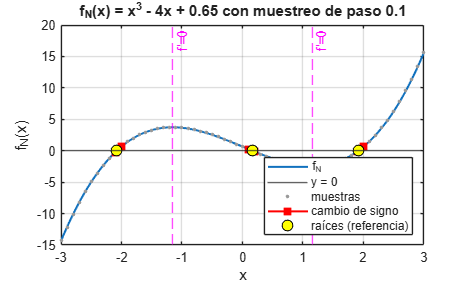

xx = linspace(-3, 3, 600);
theme(figure('Name', '2.1'), 'light');   % tema claro para el PDF
plot(xx, f(xx), 'LineWidth', 1.5); hold on; grid on; yline(0, '-');
plot(x21, f21, '.', 'Color', [0.6 0.6 0.6], 'MarkerSize', 8);
plot([x21(idx) x21(idx+1)]', [f21(idx) f21(idx+1)]', 'rs-', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
plot(raicesRef, zeros(3,1), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
xline([-2 2]/sqrt(3), 'm--', {'f''=0', 'f''=0'});
xlabel('x'); ylabel('f_N(x)');
title(sprintf('f_N(x) = x^3 - 4x + %.2f con muestreo de paso 0.1', c));
legend('f_N', 'y = 0', 'muestras', 'cambio de signo', '', '', 'raíces (referencia)', 'Location', 'southeast');
hold off

**Qué se puede concluir.** Hay exactamente tres intervalos de longitud 0.1 con cambio de signo (`Tcambios`), como se predijo; por continuidad y grado 3, cada uno contiene exactamente una raíz, localizada con incertidumbre $\pm0.05$. **Qué no.** El muestreo no detecta raíces sin cambio de signo entre muestras (dos raíces en un mismo subintervalo o una raíz doble: si $c\to16/(3\sqrt3)\approx3.08$ las dos raíces positivas se funden en $x_c$), no da más precisión que el paso ni la multiplicidad, y para una función no polinómica no acota cuántas raíces hay ni detecta discontinuidades entre muestras (caso $1/x$).

### 2.2 Bisección y falsa posición en [1, 3]

**Predicción.** En bisección el paso entre puntos medios es $(b-a)/2^n$: $E_a\le10^{-8}$ exige $n\ge\log_2(2/10^{-8})\approx27.6$, y el residuo ($|x-x^\ast|\le\mathrm{tol}_f/f'(x^\ast)\approx 1.4\times10^{-9}$) puede añadir alguna iteración: unas 28–31. La gráfica muestra que en $[1,3]$ $f$ es convexa ($f''>0$) y muy asimétrica ($|f(3)|=15+c \gg |f(1)|=3-c$): en falsa posición el extremo $b=3$ quedará **fijo** y los iterados se acercarán solo por la izquierda, linealmente con razón


$$C \approx 1 - \frac{f'(x^\ast)\,(3-x^\ast)}{f(3)} \approx 0.5 ,$$


igual a la de la bisección. **Predicción:** falsa posición **no** necesitará menos iteraciones; probablemente algunas más.

fprintf('Predicción: bisección >= %d iteraciones; razón de falsa posición C = %.3f\n', ...
    ceil(log2(2/tolx)), 1 - df(rRef)*(3 - rRef)/f(3));

Predicción: bisección >= 28 iteraciones; razón de falsa posición C = 0.515


oBis = biseccion(f, 1, 3, tolx, tolf, maxit);
oFP  = falsaPosicion(f, 1, 3, tolx, tolf, maxit);
T22 = [filaResumen("Bisección [1,3]", oBis, rRef, raicesRef); ...
       filaResumen("Falsa posición [1,3]", oFP, rRef, raicesRef)];
resumen22 = T22(:, 1:7)

resumen22 = 2×7 table
             Caso              Raiz      Residuo      ErrorPaso     Iter    Evals      Estado   
    ______________________    ______    __________    __________    ____    _____    ___________

    "Bisección [1,3]"         1.9132    6.9988e-10    7.4506e-09     28     "30"     "convergio"
    "Falsa posición [1,3]"    1.9132    9.3531e-09    1.2607e-09     32     "34"     "convergio"

	Get insights using Copilot


disp('Últimas iteraciones de falsa posición:');  disp(tail(oFP.hist(:, 1:6), 3));

Últimas iteraciones de falsa posición:
    n       a       b      x          f(x)            Ea    
    __    ______    _    ______    ___________    __________

    30    1.9132    3    1.9132    -3.5235e-08    4.7493e-09
    31    1.9132    3    1.9132    -1.8154e-08    2.4469e-09
    32    1.9132    3    1.9132    -9.3531e-09    1.2607e-09



eFP = abs(oFP.hist.x - rRef);  razFP = eFP(2:end)./eFP(1:end-1);
fprintf('Falsa posición: b fijo en 3 todo el tiempo: %s; razón observada e(n+1)/e(n) = %.3f\n', ...
    string(all(oFP.hist.b == 3)), median(razFP(5:end-2)));

Falsa posición: b fijo en 3 todo el tiempo: true; razón observada e(n+1)/e(n) = 0.515


**Contraste.** Ambos terminan en `convergio` con la misma raíz (`ErrorRef` entre $10^{-10}$ y $10^{-9}$). La bisección quedó en el rango previsto; falsa posición necesitó **más** iteraciones, con $b=3$ fijo y una razón observada igual a la $C$ calculada antes de iterar. Ambos cuestan una evaluación de $f$ por iteración (más dos iniciales); su ventaja no es la velocidad sino la **garantía** de permanecer en un intervalo con cambio de signo.

### 2.3 Punto fijo: dos reformulaciones


$$g_1(x)=\sqrt[3]{4x-c},\quad g_1'(x)=\frac{4}{3(4x-c)^{2/3}};\qquad g_2(x)=\frac{x^3+c}{4},\quad g_2'(x)=\frac{3x^2}{4};\qquad x_0=2 .$$


**Predicción.** Cerca de $x^\ast\approx1.9$: $g_1'(x^\ast)\approx4/(3\cdot3.7)\approx0.36<1$ (contractiva) y $g_2'(x^\ast)\approx2.7>1$ (repulsiva). Además $g_1([1,3])\subset[1,3]$ y $\max_{[1,3]}|g_1'|=g_1'(1)<1$: el teorema de punto fijo **garantiza** convergencia lineal de $g_1$, con razón $\approx0.36$ (unas 20 iteraciones). Con $g_2$, como $g_2(2)=(8+c)/4>2$, la sucesión crece monótonamente y diverge.

g1  = @(x) nthroot(4*x - c, 3);   dg1 = @(x) 4./(3*nthroot(4*x - c, 3).^2);
g2  = @(x) (x.^3 + c)/4;          dg2 = @(x) 3*x.^2/4;
v = linspace(rRef - 0.25, rRef + 0.25, 101);
fprintf('En [x*-0.25, x*+0.25]: |g1''| en [%.3f, %.3f];  |g2''| en [%.3f, %.3f]\n', ...
    min(dg1(v)), max(dg1(v)), min(dg2(v)), max(dg2(v)));

En [x*-0.25, x*+0.25]: |g1'| en [0.333, 0.404];  |g2'| en [2.075, 3.510]


fprintf('g1([1,3]) = [%.3f, %.3f] dentro de [1,3];  max |g1''| en [1,3] = |g1''(1)| = %.3f\n', ...
    g1(1), g1(3), dg1(1));

g1([1,3]) = [1.496, 2.247] dentro de [1,3];  max |g1'| en [1,3] = |g1'(1)| = 0.596


oG1 = puntoFijo(g1, f, 2, tolx, tolf, maxit);
oG2 = puntoFijo(g2, f, 2, tolx, tolf, maxit);
disp('g1, x0 = 2:');  disp(oG1.hist);

g1, x0 = 2:
    n      x_n      g(x_n)    |f(g(x_n))|        Ea            Er    
    __    ______    ______    ___________    __________    __________

     1         2    1.9443       0.22281       0.055704       0.02865
     2    1.9443    1.9244      0.079396       0.019849      0.010314
     3    1.9244    1.9173      0.028691      0.0071727     0.0037411
     4    1.9173    1.9147      0.010421      0.0026052     0.0013607
     5    1.9147    1.9137      0.003792     0.00094801    0.00049537
     6    1.9137    1.9134     0.0013808      0.0003452    0.00018041
     7    1.9134    1.9133    0.00050292     0.00012573    6.5715e-05
     8    1.9133    1.9132    0.00018319     4.5798e-05    2.3938e-05
     9    1.9132    1.9132     6.673e-05     1.6683e-05    8.7198e-06
    10    1.9

disp('g2, x0 = 2:');  disp(oG2.hist);

g2, x0 = 2:
    n     x_n        g(x_n)      |f(g(x_n))|        Ea           Er   
    _    ______    __________    ___________    __________    ________

    1         2        2.1625        2.1127         0.1625    0.075145
    2    2.1625        2.6907        9.3672        0.52818      0.1963
    3    2.6907        5.0325        107.97         2.3418     0.46534
    4    5.0325        32.025         32719         26.993     0.84286
    5    32.025        8211.7    5.5374e+11         8179.7      0.9961
    6    8211.7    1.3843e+11     2.653e+33     1.3843e+11           1



razG1 = oG1.hist.Ea(2:end)./oG1.hist.Ea(1:end-1);
fprintf('g1: %s en %d it.; razón Ea(n+1)/Ea(n) = %.4f vs |g1''(x*)| = %.4f\n', ...
    oG1.estado, oG1.iter, median(razG1(3:end)), dg1(rRef));

g1: convergio en 18 it.; razón Ea(n+1)/Ea(n) = 0.3643 vs |g1'(x*)| = 0.3643


fprintf('g2: %s en %d it.\n', oG2.estado, oG2.iter);

g2: divergio en 6 it.


oG2b = puntoFijo(g2, f, 0.5, tolx, tolf, maxit);
fprintf('g2 con x0 = 0.5: %s a x = %.8f (raíz central), donde |g2''| = %.3f\n', ...
    oG2b.estado, oG2b.raiz, dg2(raicesRef(2)));

g2 con x0 = 0.5: convergio a x = 0.16359458 (raíz central), donde |g2'| = 0.020


**Contraste.** $g_1$ converge y su razón observada coincide con $|g_1'(x^\ast)|$ calculada antes de iterar; $g_2$ diverge en pocas iteraciones, multiplicando el error por un factor cada vez mayor. La misma $g_2$ converge a la raíz central, donde $|g_2'|\ll1$: la contractividad es propiedad del par (reformulación, raíz), no de la ecuación. El punto fijo no requiere derivadas, pero su velocidad está limitada por $|g'(x^\ast)|$.

### 2.4 Newton–Raphson y secante

**Newton.** $x_0=2.5$: a la derecha de la raíz, zona convexa y creciente ($f(x_0)f''(x_0)>0$, Fourier): convergencia monótona y cuadrática en 5–7 iteraciones. $x_0=1.16$ y $x_0=1.15$, a ambos lados de $x_c\approx1.1547$: tangente casi horizontal, primer paso $-f/f'\approx2.4/0.03$, es decir $x_1\approx\pm70$; desde $+70$ regresará lentamente ($x_{n+1}\approx2x_n/3$) a la raíz positiva y desde $-70$ llegará a la raíz **negativa**, con estado `convergio` pero a una raíz no buscada. $x_0=2/\sqrt3$: $f'$ numéricamente nula, estado `derivada_pequena`.

**Secante.** Par A $(1.5, 2.5)$: ambos en la zona creciente, encierran la raíz; convergencia superlineal (orden $\approx1.618$) en unas 7 iteraciones. Par B $(1.0, 1.3)$: casi simétricos respecto a $x_c$ con $f(1)\approx f(1.3)$; secante casi horizontal, primer salto enorme y trayectoria errática.

x0N = [2.5, 1.16, 1.15, 2/sqrt(3)];
oN = cell(size(x0N));
for k = 1:numel(x0N)
    oN{k} = newtonRaphson(f, df, x0N(k), tolx, tolf, maxit, tolDer);
end
oSA = secante(f, 1.5, 2.5, tolx, tolf, maxit);
oSB = secante(f, 1.0, 1.3, tolx, tolf, maxit);
disp('Newton, x0 = 2.5:');                           disp(oN{1}.hist(:, [1 2 4 5 6 7]));

Newton, x0 = 2.5:
    n     x_n      f'(x_n)    x_{n+1}     r_{n+1}          Ea    
    _    ______    _______    _______    __________    __________

    1       2.5     14.75     2.0746         1.2804       0.42542
    2    2.0746    8.9116     1.9309        0.12551       0.14368
    3    1.9309    7.1851     1.9134      0.0017623      0.017468
    4    1.9134    6.9837     1.9132      3.655e-07    0.00025234
    5    1.9132    6.9808     1.9132     1.6542e-14    5.2358e-08
    6    1.9132    6.9808     1.9132     1.2212e-15    2.4425e-15



disp('Newton, x0 = 1.15 (primeras y últimas):');     disp(oN{3}.hist([1:3 end-1:end], [1 2 4 5 6 7]));

Newton, x0 = 1.15 (primeras y últimas):
    n       x_n      f'(x_n)    x_{n+1}     r_{n+1}          Ea    
    __    _______    _______    _______    __________    __________

     1       1.15    -0.0325    -73.592    3.9827e+05        74.742
     2    -73.592      16243    -49.074    1.1798e+05        24.519
     3    -49.074     7220.7    -32.734         34943         16.34
    14    -2.0768     8.9392    -2.0768    1.9289e-09    1.7595e-05
    15    -2.0768      8.939    -2.0768    3.3307e-16    2.1578e-10



disp('Secante, par A:');                             disp(oSA.hist(:, [1 4 5 6]));

Secante, par A:
    n    x_{n+1}     r_{n+1}          Ea    
    _    _______    __________    __________

    1    1.7394         1.0451       0.76061
    2     1.848          0.431       0.10859
    3    1.9242       0.077632      0.076216
    4    1.9126      0.0042709      0.011633
    5    1.9132     3.8459e-05    0.00060661
    6    1.9132     1.9364e-08    5.5121e-06
    7    1.9132     8.7375e-14    2.7739e-09



disp('Secante, par B (primeras 5):');                disp(oSB.hist(1:5, [1 4 5 6]));

Secante, par B (primeras 5):
    n    x_{n+1}     r_{n+1}          Ea    
    _    _______    __________    __________

    1      -234     1.2812e+07         235.3
    2       1.3          2.353         235.3
    3    1.3001         2.3529    4.3214e-05
    4     3.498          29.46        2.1979
    5    1.4626         2.0715        2.0354



fprintf('Newton desde 2/sqrt(3): f''(x0) = %.1e -> %s\n', df(x0N(4)), oN{4}.estado);

Newton desde 2/sqrt(3): f'(x0) = 8.9e-16 -> derivada_pequena


fprintf('Primer salto: Newton 1.16 -> x1 = %.1f;  Newton 1.15 -> x1 = %.1f;  secante B -> x2 = %.0f\n', ...
    oN{2}.hist.("x_{n+1}")(1), oN{3}.hist.("x_{n+1}")(1), oSB.hist.("x_{n+1}")(1));

Primer salto: Newton 1.16 -> x1 = 67.2;  Newton 1.15 -> x1 = -73.6;  secante B -> x2 = -234


lejos = find(oSB.hist.("r_{n+1}") > 1);
[EaMin, kMin] = min(oSB.hist.Ea(lejos));
fprintf('Secante B, iteración %d: Ea = %.1e pero residuo = %.2f  (paso pequeño SIN convergencia)\n', ...
    lejos(kMin), EaMin, oSB.hist.("r_{n+1}")(lejos(kMin)));

Secante B, iteración 3: Ea = 4.3e-05 pero residuo = 2.35  (paso pequeño SIN convergencia)


**Contraste.** Desde 2.5 Newton converge monótonamente y las cifras correctas se duplican en cada paso final ($E_a$: $\sim10^{-4}\to10^{-8}\to10^{-15}$). Las semillas junto a $x_c$ confirman la predicción: primer paso del orden de $\pm70$, fase de regreso lineal con $E_r\approx0.5$ y llegada a la raíz positiva (1.16) o **negativa** (1.15). En $x_c$ la derivada calculada es $\sim10^{-15}$ (no cero exacto) y el control evita un paso $\sim10^{15}$. Con el par B la secante salta a las centenas negativas; como $|f(x_2)|$ es enorme, la siguiente secante devuelve el iterado casi a 1.3 y aparece un **paso diminuto con** $|f|>2$: con un criterio solo de paso (y una tolerancia algo más laxa) se habría declarado convergencia falsa.

### Comparación global del punto 2

`Evals`: evaluaciones de $f$ (Newton: $f$ + $f'$). `ErrorRef`: error respecto a la raíz positiva; `RaizAlcanzada`: raíz a la que llegó cada ejecución.

T2 = [T22; ...
      filaResumen("Punto fijo g1, 2", oG1, rRef, raicesRef); ...
      filaResumen("Punto fijo g2, 2", oG2, rRef, raicesRef); ...
      filaResumen("Newton 2.5", oN{1}, rRef, raicesRef); ...
      filaResumen("Newton 1.16", oN{2}, rRef, raicesRef); ...
      filaResumen("Newton 1.15", oN{3}, rRef, raicesRef); ...
      filaResumen("Newton 2/sqrt(3)", oN{4}, rRef, raicesRef); ...
      filaResumen("Secante (1.5,2.5)", oSA, rRef, raicesRef); ...
      filaResumen("Secante (1.0,1.3)", oSB, rRef, raicesRef)];
resumenMetricas = T2(:, 1:6)

resumenMetricas = 10×6 table
             Caso                Raiz        Residuo      ErrorPaso     Iter     Evals 
    ______________________    __________    __________    __________    ____    _______

    "Bisección [1,3]"             1.9132    6.9988e-10    7.4506e-09     28     "30"   
    "Falsa posición [1,3]"        1.9132    9.3531e-09    1.2607e-09     32     "34"   
    "Punto fijo g1, 2"            1.9132    7.5365e-09    1.8841e-09     18     "18"   
    "Punto fijo g2, 2"        1.3843e+11     2.653e+33    1.3843e+11      6     "6"    
    "Newton 2.5"                  1.9132    1.2212e-15    2.4425e-15      6     "7+6"  
    "Newton 1.16"                 1.9132    1.2212e-15    7.8535e-10     15     "16+15"
    "Newton 1.15"                -2.0768    3.3307e-16    2.15

resumenEstados = T2(:, ["Caso", "Estado", "ErrorRef", "RaizAlcanzada"])

resumenEstados = 10×4 table
             Caso                   Estado           ErrorRef     RaizAlcanzada
    ______________________    __________________    __________    _____________

    "Bisección [1,3]"         "convergio"           1.0026e-10     "positiva"  
    "Falsa posición [1,3]"    "convergio"           1.3398e-09     "positiva"  
    "Punto fijo g1, 2"        "convergio"           1.0796e-09     "positiva"  
    "Punto fijo g2, 2"        "divergio"            1.3843e+11     "ninguna"   
    "Newton 2.5"              "convergio"           4.4409e-16     "positiva"  
    "Newton 1.16"             "convergio"           4.4409e-16     "positiva"  
    "Newton 1.15"             "convergio"                 3.99     "negativa"  
    "Newton 2/sqrt(3)"        "derivada_pequena"       0.75848     "ninguna"   
    "Secante (1.5,2.5)"       "conv

seqs = {oBis.hist.x, oFP.hist.x, oG1.hist.("g(x_n)"), [2.5; oN{1}.hist.("x_{n+1}")], ...
        [1.5; 2.5; oSA.hist.("x_{n+1}")]};
[pEst, razEst] = cellfun(@(xs) ordenConvergencia(xs, rRef), seqs);
Torden = table(["Bisección"; "Falsa posición"; "Punto fijo g1"; "Newton (2.5)"; "Secante A"], ...
    pEst', razEst', 'VariableNames', {'Metodo','OrdenEstimado','RazonMedia'})

Torden = 5×3 table
         Metodo         OrdenEstimado    RazonMedia
    ________________    _____________    __________

    "Bisección"             1.164          0.46664 
    "Falsa posición"            1          0.52453 
    "Punto fijo g1"             1          0.36408 
    "Newton (2.5)"         1.9394         0.017283 
    "Secante A"              1.59         0.067986 

	Get insights using Copilot


### Resultado gráfico requerido

**Figura 1:** residuo frente a iteración (los residuos nulos se dibujan en $10^{-16}$).

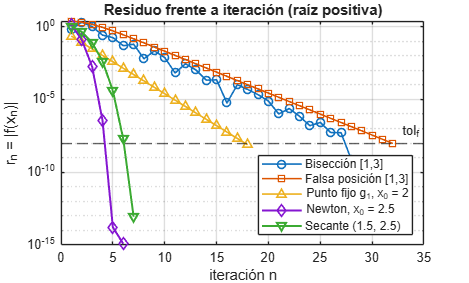

piso = 1e-16;
theme(figure('Name', 'Figura 1'), 'light');
semilogy(oBis.hist.n, max(abs(oBis.hist.("f(x)")), piso), 'o-', 'LineWidth', 1.2); hold on; grid on
semilogy(oFP.hist.n,  max(abs(oFP.hist.("f(x)")),  piso), 's-', 'LineWidth', 1.2);
semilogy(oG1.hist.n,  max(oG1.hist.("|f(g(x_n))|"), piso), '^-', 'LineWidth', 1.2);
semilogy(oN{1}.hist.n, max(oN{1}.hist.("r_{n+1}"), piso), 'd-', 'LineWidth', 1.5);
semilogy(oSA.hist.n,  max(oSA.hist.("r_{n+1}"), piso), 'v-', 'LineWidth', 1.5);
yline(tolf, '--', 'tol_f');
xlabel('iteración n'); ylabel('r_n = |f(x_n)|');
legend('Bisección [1,3]', 'Falsa posición [1,3]', 'Punto fijo g_1, x_0 = 2', ...
    'Newton, x_0 = 2.5', 'Secante (1.5, 2.5)', 'Location', 'southeast');
title('Residuo frente a iteración (raíz positiva)'); hold off

**Figura 2:** sensibilidad y fallas por datos iniciales inadecuados (código de la gráfica en `funciones/figuraSensibilidad.m`): (a) tangentes y secante casi horizontales cerca de $f'=0$; (b) trayectorias; (c) residuos; (d) punto fijo contractivo frente a repulsivo.

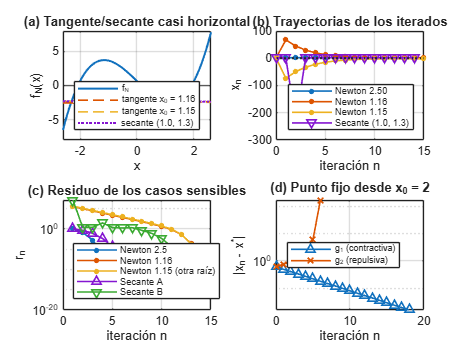

figuraSensibilidad(f, df, x0N, oN, oSA, oSB, oG1, oG2, raicesRef, rRef);

### Análisis del punto 2

fprintf('GARANTÍA:     bisección %d it. y falsa posición %d it. (%s); g1 %s en %d it.; g2 %s\n', ...
    oBis.iter, oFP.iter, oBis.estado, oG1.estado, oG1.iter, oG2.estado);

GARANTÍA:     bisección 28 it. y falsa posición 32 it. (convergio); g1 convergio en 18 it.; g2 divergio


fprintf('VELOCIDAD:    orden: FP %.2f, g1 %.2f, Newton %.2f, secante %.2f\n', pEst(2:5));

VELOCIDAD:    orden: FP 1.00, g1 1.00, Newton 1.94, secante 1.59


fprintf('              razón media: bisección %.2f, FP %.2f, g1 %.2f\n', razEst(1:3));

              razón media: bisección 0.47, FP 0.52, g1 0.36


fprintf('SENSIBILIDAD: Newton 2.5 -> %d it.; 1.16 -> %d it.; 1.15 -> raíz %.4f (%s)\n', ...
    oN{1}.iter, oN{2}.iter, oN{3}.raiz, oN{3}.estado);

SENSIBILIDAD: Newton 2.5 -> 6 it.; 1.16 -> 15 it.; 1.15 -> raíz -2.0768 (convergio)


fprintf('              Newton 2/sqrt(3) -> %s; secante A %d it. vs B %d it.\n', ...
    oN{4}.estado, oSA.iter, oSB.iter);

              Newton 2/sqrt(3) -> derivada_pequena; secante A 7 it. vs B 13 it.


fprintf('COSTO:        evaluaciones: bisección %d, FP %d, g1 %d (g) + %d (f), Newton %d (f) + %d (f''), secante %d\n', ...
    oBis.nevalf, oFP.nevalf, oG1.iter, oG1.nevalf, oN{1}.nevalf, oN{1}.nevaldf, oSA.nevalf);

COSTO:        evaluaciones: bisección 30, FP 34, g1 18 (g) + 18 (f), Newton 7 (f) + 6 (f'), secante 9


**Garantía.** Solo bisección y falsa posición convergen a partir de un dato verificable (cambio de signo y continuidad), sin semillas, a cambio de unas 30 iteraciones. $g_1$ también tiene garantía, pero porque se verificó **antes** $g_1([1,3])\subset[1,3]$ y $|g_1'|<1$; con $g_2$ la condición falla y diverge. Newton y secante no tienen garantía global.

**Velocidad local.** Falsa posición y $g_1$ son lineales (razones $\approx0.5$ y $\approx0.36$, las predichas), la secante es superlineal (orden $\approx1.6$) y Newton cuadrático (orden $\approx2$). La bisección no tiene orden bien definido (su error no es monótono) pero su razón media es $\approx1/2$. Con buenas semillas Newton (6 it.) y secante (7 it.) usan unas cinco veces menos iteraciones.

**Sensibilidad.** Esa velocidad es local: moviendo la semilla de Newton solo 0.01 (1.16 → 1.15) se pasa de 15 iteraciones hacia la raíz positiva a converger, con estado `convergio` y residuo $\sim10^{-15}$, a la raíz **negativa**. Estado y residuo no bastan: hay que contrastar con la raíz buscada (`RaizAlcanzada`). La secante con el par B salta lejos y necesita casi el doble de iteraciones que con el par A.

**Costo por iteración.** Bisección, falsa posición y secante usan una evaluación de $f$ por iteración; Newton usa $f$ y $f'$; el punto fijo una de $g$ (más una de $f$ si se vigila el residuo). Por eso la secante (9 evaluaciones) compite con Newton (13) pese a su menor orden: la comparación justa es por evaluaciones, no por iteraciones.

**Conclusión (sin ganador universal).** Con solo un intervalo con cambio de signo, el método cerrado es la elección segura; con una semilla en la zona monótona (Fourier) y $f'$ barata, Newton es el más rápido; sin $f'$, la secante con semillas cercanas ofrece la mejor relación costo/velocidad. Lo robusto es localizar con bisección y refinar con Newton o secante, vigilando $|f'|$ y la raíz alcanzada.

### Actualización parcial de la tabla diagnóstica (fila b)

Se añade a `T1` una columna de evidencia (filas a, c y d pendientes de los puntos 3 a 6).

evidencia = repmat("Pendiente (puntos 3-6)", height(T1), 1);
evidencia(2) = sprintf(['3 raíces reales. Bisección %d it., FP %d it. (b fijo), g1 %d it., g2 diverge.\n' ...
    'Newton(2.5) %d it., Newton(1.15) -> raíz %.3f; secante A %d it., B %d it.'], ...
    oBis.iter, oFP.iter, oG1.iter, oN{1}.iter, oN{3}.raiz, oSA.iter, oSB.iter);
T1 = addvars(T1, evidencia, 'NewVariableNames', 'Evidencia');
fprintf('Fila b (%s; método inicial: %s). Evidencia:\n%s\n', T1.Tipo(2), T1.MetodoInicial(2), T1.Evidencia(2));

Fila b (No lineal; método inicial: Bisección + Newton). Evidencia:
3 raíces reales. Bisección 28 it., FP 32 it. (b fijo), g1 18 it., g2 diverge.
Newton(2.5) 6 it., Newton(1.15) -> raíz -2.077; secante A 7 it., B 13 it.
